# **Training CN-vs-MCIc**

Due to memory (RAM) and computational power limits, instead of converting each MRI in one hundred pictures, in this code we are going to extract only 8 slices for each MRI, train on 3 folds instead of 20, and not perform any data augmentation.

### **Code structure:**

**1) Define the network (Transfer Learning from AlexNet)**

**2) Set training parameters**

**3) Load the Dataset:**

- Load .mat files

- Concatenate CN_training, CN_testing, etc... in a single cell array

- Transform the 238 MRI images into 1904 (=238*8) 227x227x3 images (~2GB)

**4) Cross Fold Validation (for 3 folds):**

- Find patterns to use for Testing (index==fold) and Training (index!=fold) and split the dataset in Training and Testing for this fold

- Shuffle the trainingImages (and their labels, respectively)

- Train

- Save the trained model

- Validate on TestSet

- Compute Metrics

## **Problem parameters**

clear all
warning off

% Type of problem
problem="CN_vs_MCIc";
%problem="CN_vs_AD";
%problem="MCInc_vs_MCIc";


nPictures=2; %for each axis, tot = n^3
gap=32;
dim=32; %32x32


%---------------------------------------------------------------
time=datestr(now,"yyyy_mm_dd_HH_MM"); %Save execution time

% where to save current execution outputs
directory="../TrainedModels/"+problem+"/"+time+"/";
% Create directories if doesn't exist
if ~exist("../TrainedModels", 'dir')
   mkdir("../TrainedModels")
end
if ~exist("../TrainedModels/"+problem, 'dir')
   mkdir("../TrainedModels/"+problem)
end
if ~exist("../TrainedModels/"+problem, 'dir')
   mkdir("../TrainedModels/"+problem)
end
mkdir("../TrainedModels/"+problem+"/"+time)

## **1) Define the Network**

by modifing the last 3 layers of AlexNet

siz=[227 227]; % input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers;
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Set training parameters**

folds=3;

miniBatchSize = 30;
learningRate = 1e-4;
maxEpochs=20;
optimizer='adam';

options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',maxEpochs,...
    "L2Regularization",1e-04,...
    "Verbose",false,...
    'Shuffle','every-epoch', ...
    "Plots","training-progress");

## **3) Load the Dataset**

**Load CN.mat and MCIc.mat**

**Concatenate CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array
load("../../Dataset/CN.mat")
load("../../Dataset/MCIc.mat")
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
mriLabel(1:lengthClass1)=1; %Cognitive Normal = 1
mriLabel(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**Transform the 238 MRI images into 1428 (=238*6) 227x227x3 images (~1GB)**

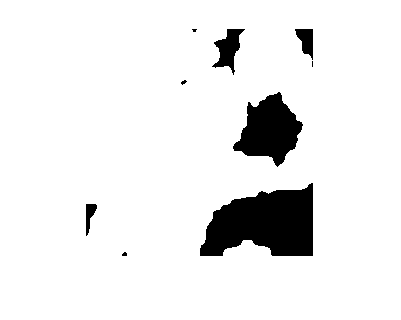

Images=[];
label=[]; % labels of classes 
labelID=[]; % labels of ID
tmpTR=1;
for i=1:length(mriLabel)
    % Extract single MRI
    IMG=dataset{i};

    % Transform MRI picture into 3 images 227x227x3
    IMG=mriToCNN(IMG,siz,nPictures,dim, gap);
    Images(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;

    % Return label vector with labels of the new 3 pictures
    class=mriLabel(i);
    label(tmpTR:tmpTR+size(IMG,4)-1)=class;

    % Save single person ID
    labelID(tmpTR:tmpTR+size(IMG,4)-1)=i;

    tmpTR=tmpTR+size(IMG,4); %Increase counter by 3

    clear IMG;
end

clear dataset mriLabel class tmpTR

% Display sample of 1 picture
a(:,:,1)=Images(:,:,1,1);
a(:,:,2)=Images(:,:,2,1);
a(:,:,3)=Images(:,:,3,1);
imshow(a(:,:,1))

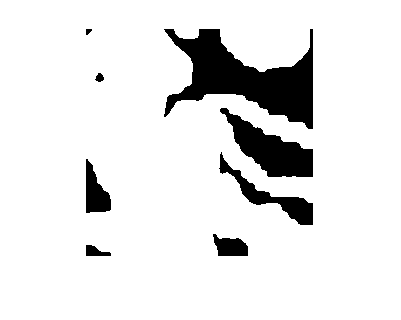

imshow(a(:,:,2))

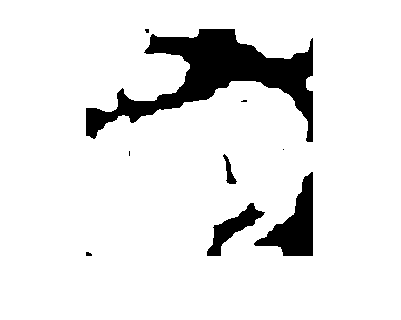

imshow(a(:,:,3))

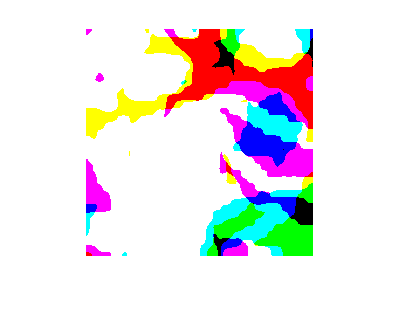

imshow(a(:,:,:))

## **4) Cross fold validation (3 fold)**

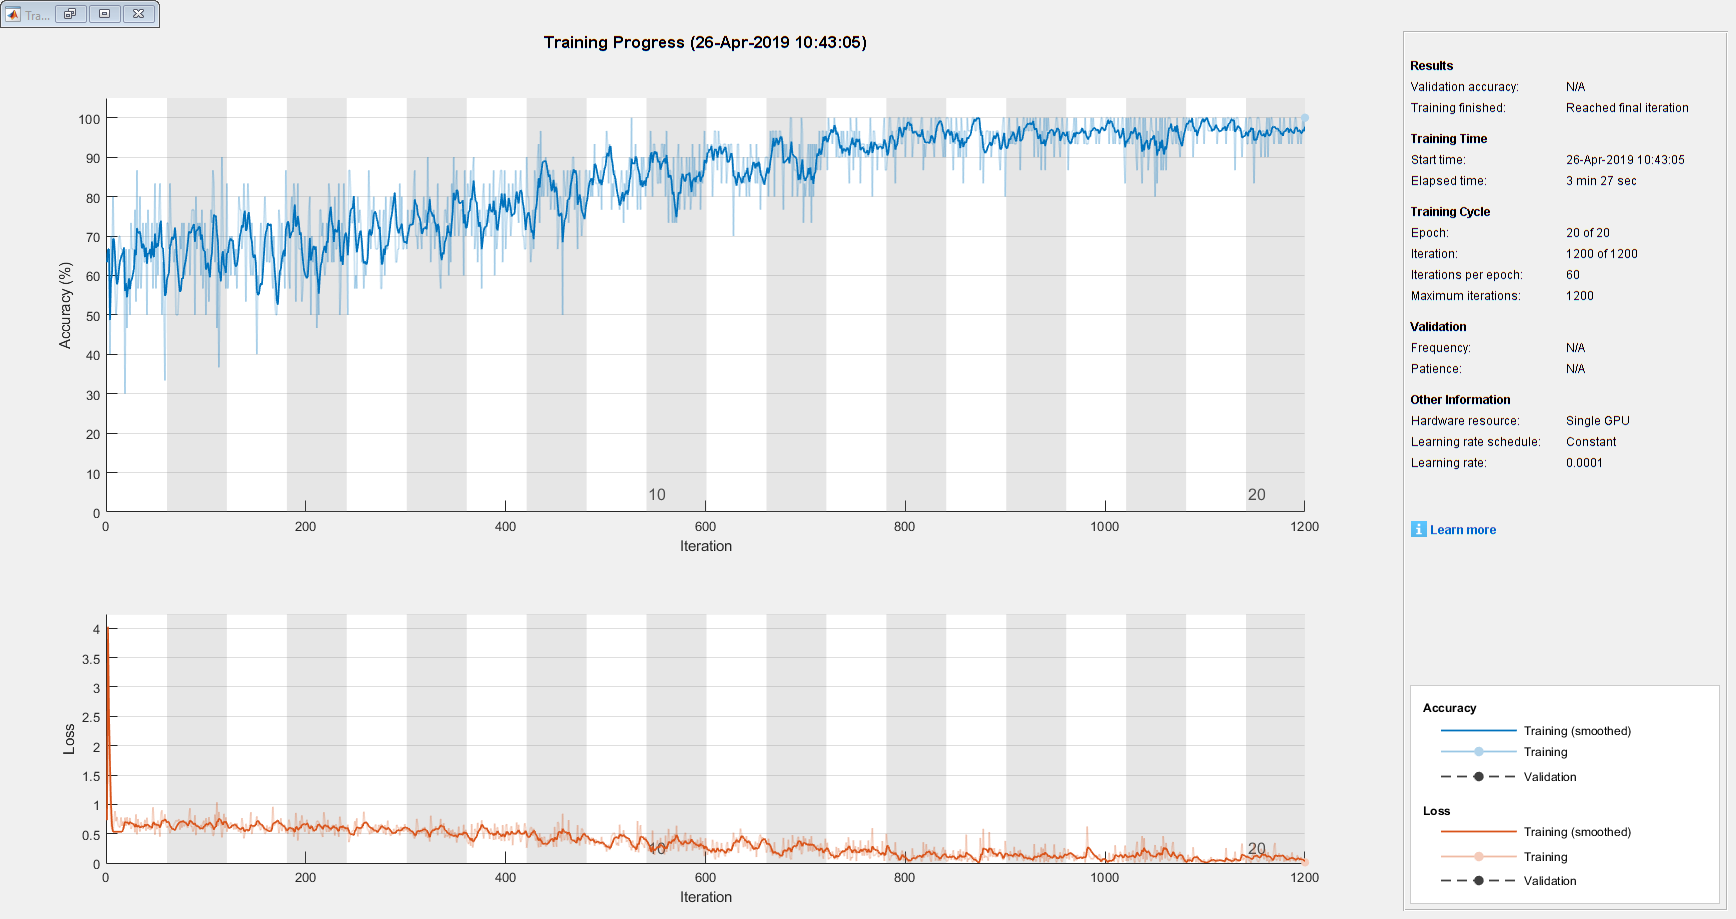

TP = 9

TN = 49

FP = 15

FN = 15

precision = 0.3750

recall = 0.3750

f1 = 0.3750

specificity = 0.2344

accuracy = 0.6591

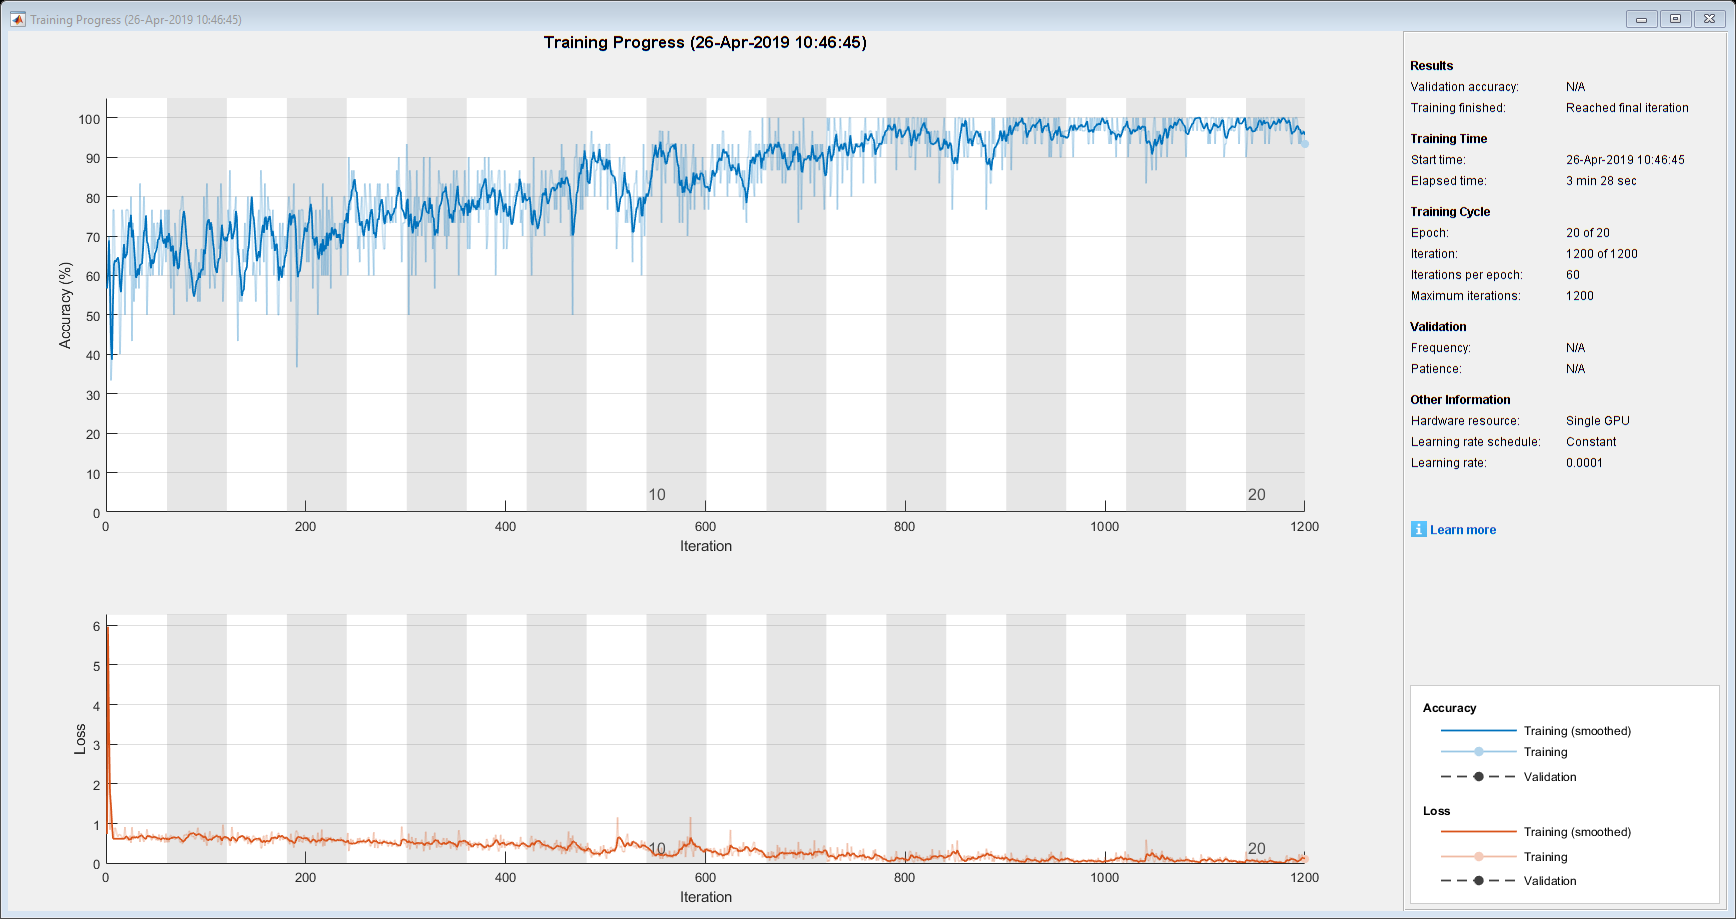

TP =      9    18


TN =     49    46


FP =     15    18


FN =     15    14


precision =     0.3750    0.5000


recall =     0.3750    0.5625


f1 =     0.3750    0.5294


specificity =     0.2344    0.2813


accuracy =     0.6591    0.6667


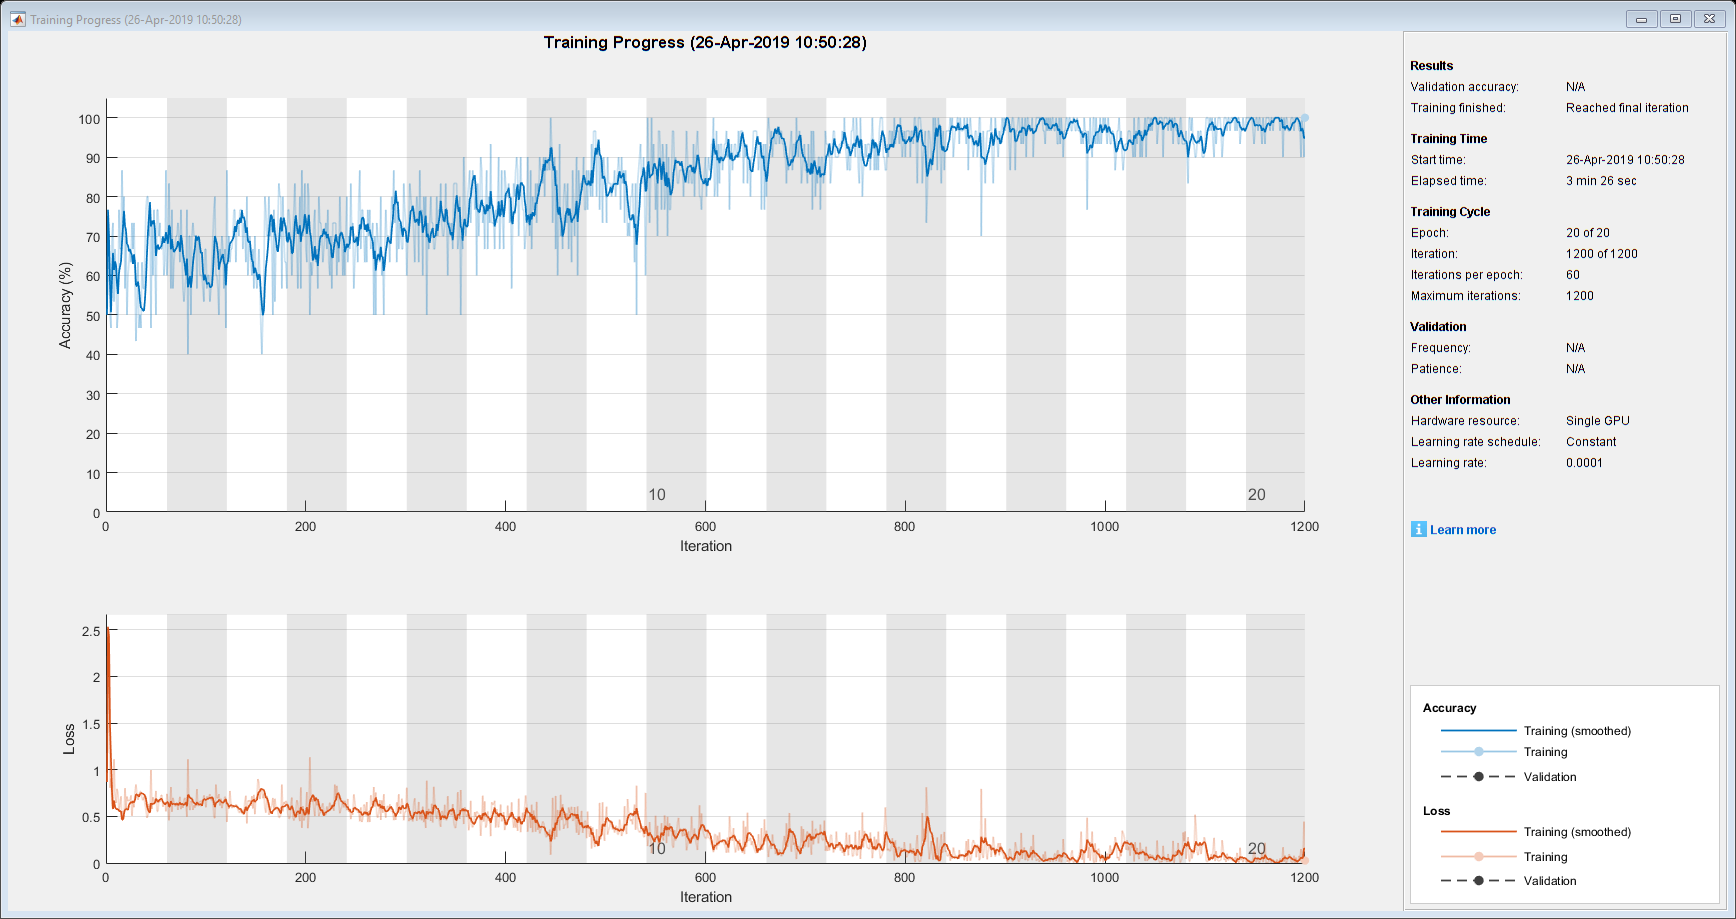

TP =      9    18     8


TN =     49    46    49


FP =     15    18    15


FN =     15    14    24


precision =     0.3750    0.5000    0.3478


recall =     0.3750    0.5625    0.2500


f1 =     0.3750    0.5294    0.2909


specificity =     0.2344    0.2813    0.2344


accuracy =     0.6591    0.6667    0.5938


for fold=1:folds

**            Find patterns to use for Testing (index==fold) and Training (index!=fold)**

    % Split the dataset in Training and Testing for this fold    
    load("../../Dataset/indices_CN-vs-MCIc.mat")
    
    trainingIndices=double([Indices~=fold])';
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);

AvarageAccuracy = 0.6398

    trainingIndices=double(ismember(labelID,trainingIndices));
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);
    
    trainingImages=Images(:,:,:,trainingIndices);
    trainingLabel=label(:,trainingIndices);
    trainingID=labelID(:,trainingIndices);
    
    testingIndices=double([Indices==fold])';
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    testingIndices=ismember(labelID,testingIndices);
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    
    testImages=Images(:,:,:,testingIndices);
    testLabel=label(:,testingIndices);
    testID=labelID(:,testingIndices);
    
    clear indices_CN-vs-MCIc.mat trainingIndices testingIndices

   **         Shuffle the trainingImages (and their labels respectively)**

    indicesVector=[1:length(trainingLabel)]; % indices from 1 to trainingImages length (~678)
    indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices
    
    trainingImages=trainingImages(:,:,:,indicesVector);
    trainingLabel=trainingLabel(:,indicesVector);
    trainingID=trainingID(:,indicesVector);

            **Train**

    valueset = [1:2];
    Y=categorical(trainingLabel',valueset);
    
    [trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);

**            Save the trained model**

    save(directory+"trainedModel"+fold+".mat", "trainedNet");
    save(directory+"trainingInfo"+fold+".mat","info");

            **Validation**

    [predictions,scores{fold}] = classify(trainedNet,testImages);

**            Metrics**

    predictions=double(predictions);

    TP(fold)= sum(and((predictions==2)',testLabel==2))
    TN(fold)= sum(and((predictions==1)',testLabel==1))
    FP(fold)= sum(and((predictions==2)',testLabel==1))
    FN(fold)= sum(and((predictions==1)',testLabel==2))
    
    precision(fold)= TP(fold)/(TP(fold)+FP(fold))
    recall(fold)=TP(fold)/(TP(fold)+FN(fold))
    f1(fold)=2*(precision(fold)*recall(fold))/(precision(fold)+recall(fold))
    specificity(fold)=FP(fold)/(FP(fold)+TN(fold))
    accuracy(fold)=(TP(fold)+TN(fold))/(TP(fold)+TN(fold)+FP(fold)+FN(fold))

    %confusionchart(testLabel,predictions)
    
    
    
end %End of cross fold validation

### **Save metrics and Scores**

save(directory+"Metrics.mat","TP","TN","FP","FN","precision","recall","f1","specificity","accuracy")

save(directory+"Scores.mat","scores");

AvarageAccuracy=sum(accuracy)/3

function [IMG]=mriToCNN(IMG,siz,nPictures,dim, gap)

    % Removing NaN values
    IMG(find(isnan(IMG)))=0;
    mriSize=size(IMG); %Size of the 3D MRI
    
    %Voxels indexes
    middleX=floor(mriSize(1)/2); %index of the middle slice on x-axis
    middleY=floor(mriSize(2)/2); %index of the middle slice on y-axis
    middleZ=floor(mriSize(3)/2); %index of the middle slice on z-axis
    for l=0:nPictures-1
        x(l+1)=middleX-floor((nPictures*(gap+1)-gap)/2)+l*(gap+1);
        y(l+1)=middleY-floor((nPictures*(gap+1)-gap)/2)+l*(gap+1);
        z(l+1)=middleZ-floor((nPictures*(gap+1)-gap)/2)+l*(gap+1);
       
    end
    
    f=1;
    for i=1:2
        for j=1:2
            for k=1:2
                xyz(1,f)=x(i);
                xyz(2,f)=y(j);
                xyz(3,f)=z(k);
                f=f+1;
            end
        end
    end
    
    sizeVoxelMatrix=size(xyz);
    for i=1:sizeVoxelMatrix(2)
        %Slice x-axis
        sliceX=imresize(squeeze(IMG(xyz(1,i),...
            xyz(2,i)-floor(dim/2):xyz(2,i)+floor(dim/2),...
            xyz(3,i)-floor(dim/2):xyz(3,i)+floor(dim/2))),[siz(1) siz(2)]);
        
        %Slice y-axis
        sliceY=imresize(squeeze(IMG(xyz(1,i)-floor(dim/2):xyz(1,i)+floor(dim/2),...
            xyz(2,i),...
            xyz(3,i)-floor(dim/2):xyz(3,i)+floor(dim/2))),[siz(1) siz(2)]);
        %Slice z-axis
        sliceZ=imresize(squeeze(IMG(xyz(1,i)-floor(dim/2):xyz(1,i)+floor(dim/2),...
            xyz(2,i)-floor(dim/2):xyz(2,i)+floor(dim/2),...
            xyz(3,i))),[siz(1) siz(2)]);
        
        RID(:,:,1,i)=sliceX;
        RID(:,:,2,i)=sliceY;
        RID(:,:,3,i)=sliceZ;
        clear sliceX sliceY sliceZ;
            
    end
    
    clear IMG
    
    % Normalize values
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
    
    clear RID
end